clear;

num_of_nodes = 7;
max_buff = 16;
cs = 10;
mean_buff = 10;
mobi = ['hete31-'; 'hete32-'; 'hete33-'; 'hete34-'];
fastNode = [3 4 5 6];

for k = 1: size(mobi,1)
    % file1 = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\buff\7n-cs' num2str(cs) '-con-buff-addr-'];
    % file1 = 'C:\Users\jzyan\Dropbox\PhDwork\opnet\data\jan2019\buff\7n_hete2_con_buff_addr_';
    file1 = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\buff\n' num2str(num_of_nodes) '-' mobi(k,:) 'con-cs' num2str(cs) '-pit6k-cl6k-rr400-'];
    
    data1 = importdata([file1 'buff-addr-time.txt']);
    data2 = importdata([file1 'buff-addr-size.txt']);
    
    
    
    buff = [data2.data data1.data(:,2)];
    datSize = size(buff((buff(:,1)==1),:));

    buff_sum = zeros(datSize(1),1);
    for i = 1:num_of_nodes
        if (i <= 2)
            continue;
        end
    %     plot(buff((buff(:,1)==i),3), buff((buff(:,1)==i),2));
        buff_sum = buff_sum + buff((buff(:,1)==i),2);
    end
    
    % uni_buff = buff_sum/(num_of_nodes-2)/buff_limit;
    uni_buff = buff_sum/(num_of_nodes-2);
% %-----------------------buff vs time------------------------------
% fig1 = figure;
% plot( buff((buff(:,1)==i),3), uni_buff );
% ylabel('mean buffer usage');
% xlabel('sec');

    uni_buff = uni_buff(ceil(15000/60):datSize(1));%remove the data collected when there is no transmission
    % disp(size(tmp(tmp==1),1)/size(tmp,1));
    % disp('buff drop ratio');
    full_smp = size( uni_buff(uni_buff/max_buff >= (cs-1)/max_buff),1) ;%get full sample
    disp( full_smp / size(uni_buff,1));

    0.4539



    % disp('simu mean buff usage');
    disp(mean(uni_buff));

    8.3195



    % disp('predicted mean buff usage');
    disp(mean_buff);

    10



    
    figure;
    h = histogram(uni_buff,'Normalization','pdf','BinWidth',1,'DisplayName','Simu',...
        'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);%, 'BinWidth',1/buff_limit
    ylabel('probability of buffer usage');
    xlabel('buffer usage');
    hold on;
    preBuff = poisspdf(1:25, mean_buff);% predicted buffer usage distribution 
    
    if (cs >= max_buff)
    %-----------------------full dist-----------------------------------------------
        plot(1:size(preBuff,2), preBuff,'DisplayName', 'Analytical','LineWidth',2,'LineStyle','--', 'Color', [0.85 0.33 0.1]);
        legend('show','Location','northeast');
    
    else
    %----------------------tail cut dist---------------------------------------
        trnPreBuff = [preBuff(1:cs-1) sum(preBuff(cs:size(preBuff,2)))];
        plot(1:size(trnPreBuff,2), trnPreBuff,'DisplayName', 'Analytical','LineWidth',2,'LineStyle','--', 'Color', [0.85 0.33 0.1]);
        legend('show','Location','northwest');
    end
    % disp('probability of drop a content');
    disp( sum( preBuff( cs+1:size(preBuff,2) ) ) );%

    0.4169



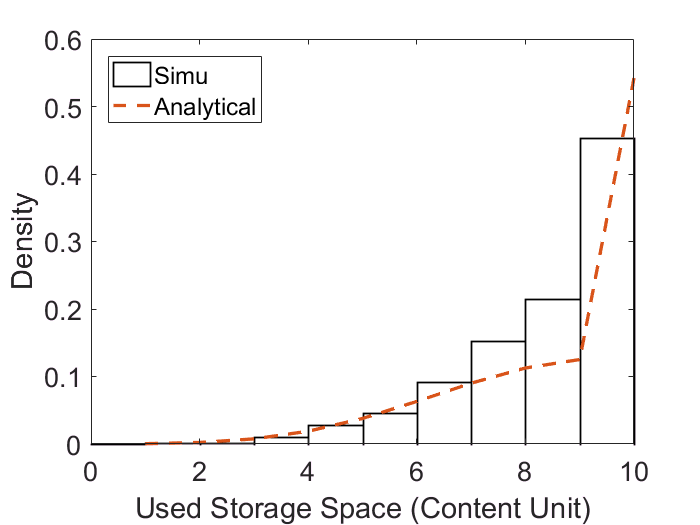

    xlabel('Used Storage Space (Content Unit)');
    ylabel('Density');
    set(gca,'FontSize',16)

%-----------------------dropped content vs time------------------------------
    if (cs <= max_buff)
        % file2 = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\buff\7n-cs' num2str(cs) '-con-buffdrop-time-'];
        % file2 = 'C:\Users\jzyan\Dropbox\PhDwork\opnet\data\jan2019\buff\7n_hete2_con_buff_addr_';
        file2 = [file1 'buffdrop-time-'];
        
        data3 = importdata([file2 'addr.txt']);
        data4 = importdata([file2 'name.txt']);
        buffdrop = [data3.data data4.data(:,2)];
        buffdrop_tmp = buffdrop(buffdrop(:,2) ~= 1,:);
        
        figure(fig1);
        hold on;
        buffdrop_sum = zeros(datSize(1),1);
        t = buff((buff(:,1)==1),3);
        j = 1;
        for i =  1:size( buffdrop_tmp, 1)
            while ( j< size(t,1) && t(j) < buffdrop_tmp(i,1) )
                        j = j+1;
            end
            buffdrop_sum(j) = buffdrop_sum(j) + 1;
            disp(j);
        end
        % figure;
        plot(t, buffdrop_sum/(num_of_nodes-2) );
        
        %-----------------------dropped content vs node id------------------------------
        ttl_drop = zeros(num_of_nodes,2);
        % buff = buff(buff(:,2)~=0,:);
        for i = 1:num_of_nodes
            ttl_drop(i,1) = i;
            ttl_drop(i,2) = size( buffdrop((buffdrop(:,2)==i),:), 1 );
        end
        
        % ttl_drop = ttl_drop(3:num_of_nodes,:);
        
        figure;
        plot(ttl_drop(:,1), ttl_drop(:,2),'o');
        ylabel('total dropped content');
        xlabel('node address');
    end

Undefined function or variable 'fig1'.

    %-----------------------fast nodes use more storage------------------------------
    mean_use = zeros(num_of_nodes,2);
    % buff = buff(buff(:,2)~=0,:);
    for i = 1:num_of_nodes
        mean_use(i,1) = i;
        mean_use(i,2) = mean(buff((buff(:,1)==i),2));
    end
    
    % mean_use = mean_use(3:num_of_nodes,:);
    % mean_use = mean_use(mean_use(:,1)~=2,:);
    
    figure;
    plot(mean_use(3:num_of_nodes,1), mean_use(3:num_of_nodes,2), 'o');
    ylabel('mean buffer usage');
    xlabel('node address');
    
    if (fastNode(k) > 2)
        fast_mbu = mean( mean_use(3:fastNode(k),2) );
        slow_mbu = mean( mean_use(fastNode(k)+1:num_of_nodes,2) );
        bar([fast_mbu/fast_mbu slow_mbu/fast_mbu]);
        ylabel('mean buffer usage');
        xlabel('fast slow');
    end
    
    %-----------------------content age vs node------------------------------
    
    file3 = [file1 'buff_age-'];
    
    data5 = importdata([file3 'age.txt']);
    data6 = importdata([file3 'name.txt']);
    buffage = [data5.data data6.data(:,2)];
    % buffage_tmp = buffage(buffage(:,1) > 2,:);
    buffage_tmp = buffage(buffage(:,1) > 2,:);
    mean_bfage = zeros(num_of_nodes,1);
    % figure;hold on;
    for i = 1:num_of_nodes
    %     figure;
    %     histogram(buffage_tmp(buffage_tmp(:,1)==i,2),'Normalization','pdf','DisplayName',['Simu' num2str(i)]);
    %     legend('show');
        mean_bfage(i) = mean( buffage_tmp(buffage_tmp(:,1)==i,2) );
    end
    figure;
    plot(mean_bfage);
    ylabel('mean buffer age');
    xlabel('node address');
    if (fastNode(k) > 2)
        fast_mba = mean( mean_bfage(3:fastNode(k)) );
        slow_mba = mean( mean_bfage(fastNode(k)+1:num_of_nodes) );
        bar([fast_mba/slow_mba slow_mba/slow_mba]);
        ylabel('mean buffer age');
        xlabel('fast slow');
    end


    %%-----------------------content delivery num vs node------------------------------
    file5 = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\lambda\n' num2str(num_of_nodes) '-' mobi(k) 'con-cs' num2str(cs) '-pit6k-cl6k-rr400-' 'occur_neighbor_addr.txt'];
    file6 = [['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\n' num2str(num_of_nodes) '-' mobi(k) 'con-cs' num2str(cs) '-pit6k-cl6k-rr400-'] 'app-name-time.txt'];
    
    rawdata = importdata(file5);
    enc = rawdata.data;
    enc = enc(enc(:,2)~=1,:);
    rawdata = importdata(file6);
    recv = rawdata.data;
    
    driver = zeros(num_of_nodes,1);
    j = 1;
    for i = 1:size(recv,1)
        while ( j< size(enc,1) && enc(j,1) < recv(i,2))
            j = j+1;
        end
        j=j-1;
    %     if (1 >= abs( enc(j,1) - recv(i,2) ))
            driver(enc(j,2)) = driver(enc(j,2)) + 1;
    %         disp(['content name ' num2str(recv(i,1)) ' recv time ' num2str(recv(i,2)) ' encounter node ' num2str(enc(j,2)) ' encounter time ' num2str(enc(j,1))]);
    %     end
    end
    figure;
    plot(driver, 'o');
    ylabel('content delivery num');
    xlabel('node address');
    
    if (fastNode(k) > 2)
        fast_cdn = mean( driver(3:fastNode(k)) );
        slow_cdn = mean( driver(fastNode(k)+1:num_of_nodes) );
        bar([fast_cdn/fast_cdn slow_cdn/fast_cdn]);
        ylabel('content delivery num');
        xlabel('fast slow');
    end


    %%-----------------------content exchange num vs node------------------------------
    file7 = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\n' num2str(num_of_nodes) '-' mobi(k) 'con-cs' num2str(cs) '-pit6k-cl6k-rr400-' 'exch.txt'];
    
    rawdata = importdata(file7);
    exch = rawdata.data;
    
    exch = exch(exch(:,2)~=2,:);
    exch_num = zeros(num_of_nodes,1);
    for i = 1:num_of_nodes
        exch_num(i) = sum( exch(:,2)==i );
    end
    % exch_num(2) = exch_num(2)-10000;
    plot(exch_num,'o');
    ylabel('content exchange num');
    xlabel('node address');
    
    if (fastNode(k) > 2)
        fast_cen = mean( exch_num(3:fastNode(k)) );
        slow_cen = mean( exch_num(fastNode(k)+1:num_of_nodes) );
        bar([fast_cen/fast_cen slow_cen/fast_cen]);
        ylabel('content exchange num');
        xlabel('fast slow');
    end
end % end of for
